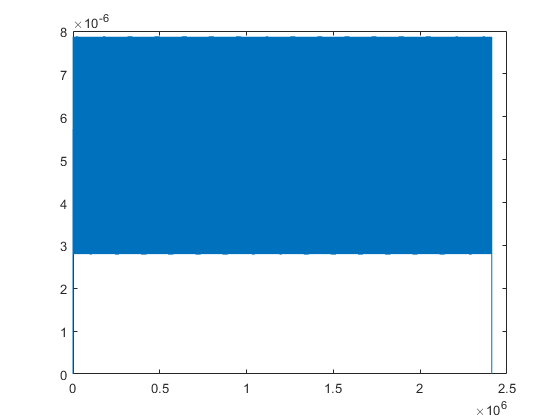

load('G.mat');
load('SOS.mat');

y_t = sig_rx;
figure;plot(y_t)


[b,a]=sos2tf(SOS,G);
y_fil=filter(b,a, y_t * 1);



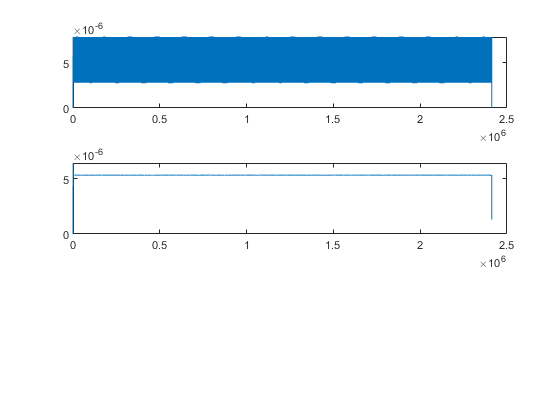

figure
subplot(3,1,1);
plot(y_t * 1);

subplot(3,1,2)
plot(y_fil);

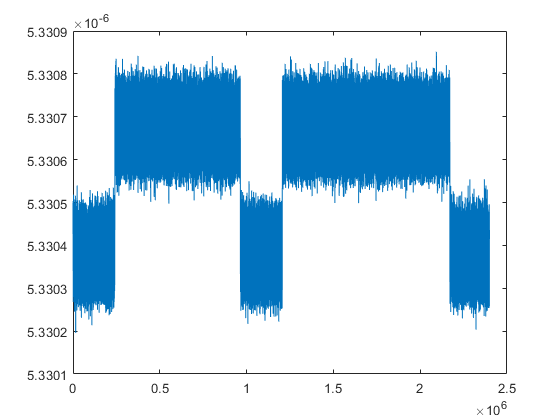

figure;
plot(y_fil(1,1000:2400000));